## Instruções

Uma rede utiliza o algoritmo **token bucket** com os seguintes parâmetros: **taxa de chegada** de fichas no balde igual a **128 mil fichas por segundo**, na qual *cada ficha habilita a transmissão de um byte*. O **tamanho do balde é de 512 mil fichas** e a **taxa de transmissão do enlace é de 4,096 Mbps (megabits por segundo)**. Admitindo que no instante t = 0 segundos o **balde esteja cheio de fichas** e que um pacote de **1 milhão de bytes**  seja recebido, faça um gráfico indicando a **duração da transmissão** à **taxa máxima** e a **duração total da transmissão** do pacote de 1 milhão de bytes.

% Token bucket (1 ficha por 1 byte)
r = 128e3 % fichas por segundo

r = 128000

b = 512e3 % fichas

b = 512000


% Enlace
R = 4.096e6 % bits por segundo

R = 4096000

R = R / 8 % bytes por segundo

R = 512000


fila = 1e6 % bytes

fila = 1000000


% tempo de máxima transmissão
t_maxima = b / (R - r) % segundos

t_maxima = 1.3333


% quantidade de bytes transmitidos durante a máxima transmissão
transmitidos_maxima = t_maxima * R % bytes

transmitidos_maxima = 6.8267e+05


% bytes restantes
restantes = fila - transmitidos_maxima % bytes

restantes = 3.1733e+05


% quantidade de tempo para transmitir o restante barrado pelo bucket
t_restante = restantes / r

t_restante = 2.4792


% duração total
t_total = t_maxima + t_restante

t_total = 3.8125


% gráfico

iter = 5;
resolution = 100

resolution = 100

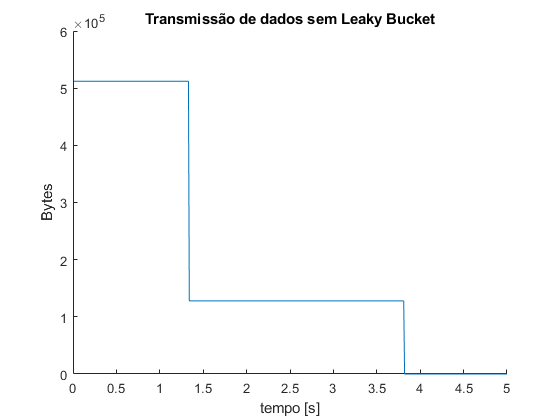


y = zeros(1, iter * resolution);

for i = 1:iter*resolution
    if (i/resolution <= t_total) && (i/resolution <= t_maxima)
        y(i) = R;
    elseif (i/resolution >= t_maxima) && (i/resolution < t_total)
        y(i) = r;
    else
        y(i) = 0;
    end
end

figure
hold on

x = 1:iter*resolution;
x = x/resolution;

title("Transmissão de dados sem Leaky Bucket")
xlabel("tempo [s]")
ylabel("Bytes")

plot(x,y)

Repita o exercício acima considerando que um **leaky bucket** com **taxa de transmissão de 256 mil bytes** por segundo foi colocado na saída do token bucket.

% Leaky bucket
R = 256e3 % bytes por segundo

R = 256000


% Token bucket (1 ficha por 1 byte)
r = 128e3 % fichas por segundo

r = 128000

b = 512e3 % fichas

b = 512000


fila = 1e6 % bytes

fila = 1000000


% tempo de máxima transmissão
t_maxima = b / (R - r) % segundos

t_maxima = 4


% quantidade de bytes transmitidos durante a máxima transmissão
transmitidos_maxima = t_maxima * R % bytes

transmitidos_maxima = 1024000


% bytes restantes
restantes = fila - transmitidos_maxima % bytes

restantes = -24000


% quantidade de tempo para transmitir o restante barrado pelo bucket
t_restante = restantes / r

t_restante = -0.1875


% duração total
t_total = t_maxima + t_restante

t_total = 3.8125


% gráfico

iter = 5;
resolution = 100

resolution = 100

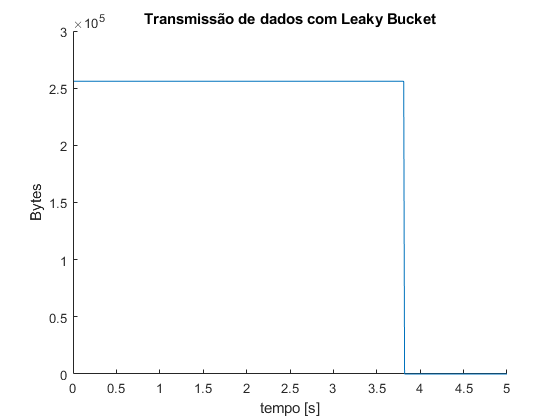


y = zeros(1, iter * resolution);

for i = 1:iter*resolution
    if (i/resolution <= t_total) && (i/resolution <= t_maxima)
        y(i) = R;
    elseif (i/resolution >= t_maxima) && (i/resolution < t_total)
        y(i) = r;
    else
        y(i) = 0;
    end
end

figure
hold on
x = 1:iter*resolution;
x = x/resolution;

title("Transmissão de dados com Leaky Bucket")
xlabel("tempo [s]")
ylabel("Bytes")

plot(x,y)